# Evaluate the Model

Instructions are in the task pane to the left. Complete and submit each task one at a time. Do not edit. This code loads the data.

load featuredata.mat
features= convertvars(features,'Character','categorical')

features = 470×3 table
    AspectRatio    Duration    Character
    ___________    ________    _________

      2.9412        0.385          V    
      3.2258        0.348          V    
      7.6923        2.759          J    
      1.7551        1.832          M    
      2.5667        0.879          V    
      3.7667         0.75          J    
        13.2        0.497          J    
      1.2963        0.662          M    
      1.6923        0.724          M    
      2.2143        0.306          V    
      3.6842        0.321          V    
      6.2174        0.451          J    
      3.6071        0.562          J    
      1.1852         0.53          M    
      1.0536        0.528          M    
      3.5294        0.421          V    


knnmodel = fitcknn(features,"Character","NumNeighbors",5);
load testdata.mat
testdata=convertvars(testdata,'Character','categorical')

testdata = 10×3 table
    AspectRatio    Duration    Character
    ___________    ________    _________

      5.7308        0.401          J    
      1.6596        0.455          M    
      2.4062        0.275          V    
      3.7568        0.856          J    
        2.32         1.36          M    
      3.6774        0.706          V    
      6.2692        0.991          J    
      7.0417        0.754          J    
      1.7222        0.583          M    
       1.525         0.57          M    


% T2 = convertvars(testdata,'Character','categorical')

## Task 1

How good is the kNN model? You can use the model to make predictions but how good are those predictions? Typically you want to test the model by having it make predictions on observations for which you know the correct classification.

The file `featuredata.mat` contains a table `testdata` that has the same variables as `features`, including the known classes for the test observations. However, the observations in `testdata` are not included in `features`. You can use the `predict` function to determine the kNN model's predictions for the observations in `testdata` and then compare the predictions to the known classes to see how well the model performs on new data.

Note that the `predict` function will ignore the `Character` variable when making predictions from the model.

**TASK1**

Use the `predict` function with the trained model `knnmodel` to classify the letters in the table `testdata`. Store the predictions in a variable called `predictions`.

**Hint1**

Pass `knnmodel` and `testdata` as inputs to the `predict` function. Assign the output to `predictions`.

predictions = predict(knnmodel,testdata)

predictions = 10×1 categorical array
     J 
     M 
     V 
     J 
     V 
     J 
     J 
     J 
     M 
     M 


## Task 2

The known classes for the test observations are stored in the variable `Character` in the table `testdata`.

**TASK2**

Use the `==` operator to compare `predictions` to the known classes. Store the result in a variable called `iscorrect`.

**Hint2**

Perform the comparison `predictions` `==` `testdata.Character`. Assign the output to `iscorrect`.

iscorrect = predictions == testdata.Character

iscorrect = 10×1 logical array
   1
   1
   1
   1
   0
   0
   1
   1
   1
   1


## Task 3

**TASK3**

Calculate the proportion of correct predictions by dividing the number of correct predictions by the total number of predictions. Store the result in a variable called `accuracy`. You can use the `sum` function to determine the number of correct predictions and the `numel` function to determine the total number of predictions.

**Hint3**

Divide `sum``(``iscorrect``)` by `numel``(``predictions``)`. Assign the result to `accuracy`.

accuracy = sum(iscorrect)/numel(predictions)

accuracy = 0.8000

## Task 4

Rather than accuracy (the proportion of correct predictions), a commonly-used metric to evaluate a model is *misclassification rate* (the proportion of incorrect predictions).

**TASK4**

Use the `~=` operator to determine the misclassification rate. Store the result in a variable called `misclassrate`.

**Hint4**

Use the same commands as in the previous two tasks, but change the `==` to `~=`.

iswrong = predictions ~= testdata.Character

iswrong = 10×1 logical array
   0
   0
   0
   0
   1
   1
   0
   0
   0
   0


misclassrate = sum(iswrong)/numel(predictions)

misclassrate = 0.2000

## Task 5

Accuracy and misclassification rate give a single value for the overall performance of the model, but it can be useful to see a more detailed breakdown of which classes the model confuses. A *confusion matrix* shows the number of observations for each combination of true and predicted class.

A confusion matrix is commonly visualized by shading the elements according to their value. Often the diagonal elements (the correct classifications) are shaded in one color and the other elements (the incorrect classifications) in another color. You can visualize a confusion matrix by using the `confusionchart` function.

`confusionchart``(``ytrue``,``ypred``)``;`

where `ytrue` is a vector of the known classes and `ypred` is a vector of the predicted classes.

**TASK5**

Use the `confusionchart` function to compare `predictions` to the known labels (stored in the variable `Character` in the table `testdata`).

**Hint5**

Pass `testdata.Character` and `predictions` as inputs to the `confusionchart` function.

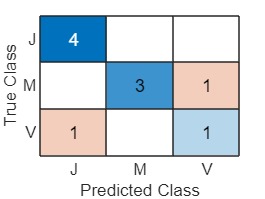

confusionchart(testdata.Character,predictions)